% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

%  
% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K)    % use this for motor with feedback

$$Hcloop = -\frac{1}{\frac{a\,b\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{l\,\left(\frac{g}{l}-s^{2}\right)\,\left(a+s\right)\,\left(\frac{a\,b\,\left(\mathrm{Jp}+\frac{\mathrm{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{a+s}+1\right)}-1}$$


% pretty(simplify(Hcloop))       % to display the total transfer function

% Substitute parameters and solve
% system parameters
g = 9.81;
l = 22*2.54/100;  %effective length 
a = 14;           %nominal motor parameters
b = 1/400;        %nominal motor parameters

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{175\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{2794\,\left(s^{2}-\frac{24525}{1397}\right)\,\left(\frac{7\,\left(\mathrm{Jp}+\frac{\mathrm{Ci}}{s^{2}}+\frac{\mathrm{Ji}}{s}\right)}{200\,\left(s+14\right)}+1\right)\,\left(s+14\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc. 

% p1 = -1 + 2*pi*i    % dominant pole pair
% p2 = -1 - 2*pi*i    % dominant pole pair 
% p3 = -10
% p4 = -8
% p5 = -8.

p1 = -1 + 2*i   % dominant pole pair

p1 = -1.0000 + 2.0000i

p2 = -1 -2*i    % dominant pole pair 

p2 = -1.0000 - 2.0000i

p3 = -6

p3 = -6

p4 = -42    % dominant pole pair

p4 = -42

p5 = -24     % dominant pole pair 

p5 = -24


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
% tgt_char_poly = (s-p1)*(s-p2)*(s-p3)

% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5)

$$tgt\_char\_poly = \left(s+6\right)\,\left(s+1-2\,\mathrm{i}\right)\,\left(s+1+2\,\mathrm{i}\right)\,\left(s+24\right)\,\left(s+42\right)$$

exp_tgt_char_poly = expand(tgt_char_poly)

$$exp\_tgt\_char\_poly = s^{5}+74\,s^{4}+1553\,s^{3}+9216\,s^{2}+19116\,s+30240$$


% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub)

$$n = \left(1397\,s^{2}-24525\right)\,\left(7\,\mathrm{Ci}+7\,\mathrm{Ji}\,s+7\,\mathrm{Jp}\,s^{2}+2800\,s^{2}+200\,s^{3}\right)$$

$$d = 9779\,\mathrm{Ci}\,s^{2}-171675\,\mathrm{Ji}\,s-171675\,\mathrm{Ci}+9779\,\mathrm{Ji}\,s^{3}-171675\,\mathrm{Jp}\,s^{2}+9779\,\mathrm{Jp}\,s^{4}+17500\,\mathrm{Ki}\,s^{2}+17500\,\mathrm{Kp}\,s^{3}-68670000\,s^{2}-4905000\,s^{3}+3911600\,s^{4}+279400\,s^{5}$$


% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s)

$$coeffs\_denom = \left(\begin{array}{cccccc} -171675\,\mathrm{Ci} & -171675\,\mathrm{Ji} & 9779\,\mathrm{Ci}-171675\,\mathrm{Jp}+17500\,\mathrm{Ki}-68670000 & 9779\,\mathrm{Ji}+17500\,\mathrm{Kp}-4905000 & 9779\,\mathrm{Jp}+3911600 & 279400 \end{array}\right)$$


% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end))

$$coeffs\_denom = \left(\begin{array}{cccccc} -\frac{6867\,\mathrm{Ci}}{11176} & -\frac{6867\,\mathrm{Ji}}{11176} & \frac{7\,\mathrm{Ci}}{200}-\frac{6867\,\mathrm{Jp}}{11176}+\frac{175\,\mathrm{Ki}}{2794}-\frac{343350}{1397} & \frac{7\,\mathrm{Ji}}{200}+\frac{175\,\mathrm{Kp}}{2794}-\frac{24525}{1397} & \frac{7\,\mathrm{Jp}}{200}+14 & 1 \end{array}\right)$$

% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s)

$$coeffs\_tgt = \left(\begin{array}{cccccc} 30240 & 19116 & 9216 & 1553 & 74 & 1 \end{array}\right)$$

% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4)

$$roots\_target = \left(\begin{array}{c} -42.0\\ -24.0\\ -6.0\\ -1.0+2.0\,\mathrm{i}\\ -1.0-2.0\,\mathrm{i} \end{array}\right)$$



% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 4.2460e+04

Ki = double(solutions.Ki)

Ki = 1.9538e+05

Ji = double(solutions.Ji)

Ji = -3.1111e+04

Jp = double(solutions.Jp)

Jp = 1.7143e+03

Ci = double(solutions.Ci)

Ci = -4.9215e+04


%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4)

$$aaa = \left(\begin{array}{cccccc} 30240.0 & 19120.0 & 9216.0 & 1553.0 & 74.0 & 1.0 \end{array}\right)$$


% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

$$check\_closed\_loop\_poles = \left(\begin{array}{c} -42.0\\ -24.0\\ -6.0\\ -1.0+2.0\,\mathrm{i}\\ -1.0-2.0\,\mathrm{i} \end{array}\right)$$


% write out target polynomial 
% bbb = vpa( expand( (s-check_closed_loop_poles(1))*(s-check_closed_loop_poles(2)) ...
%     *(s-check_closed_loop_poles(3))*(s-check_closed_loop_poles(4)) ...
%     *(s-check_closed_loop_poles(5)) ) )



% Plot impulse and step responses of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  9.067e37 s^8 + 7.979e39 s^7 - 6.387e39 s^6 - 1.678e42 s^5 - 2.102e42 s^4 + 2.701e43 s^3 + 3.839e43 s^2
  ------------------------------------------------------------------------------------------------------
  9.067e37 s^8 + 7.979e39 s^7 + 2.347e41 s^6 + 2.807e42 s^5 + 1.343e43 s^4 + 2.701e43 s^3 + 3.839e43 s^2
 
Continuous-time transfer function.


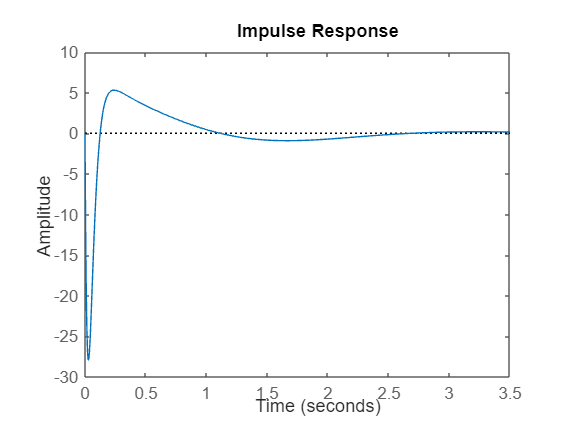

figure (1)
impulse(TFH);   %plot the impulse reponse

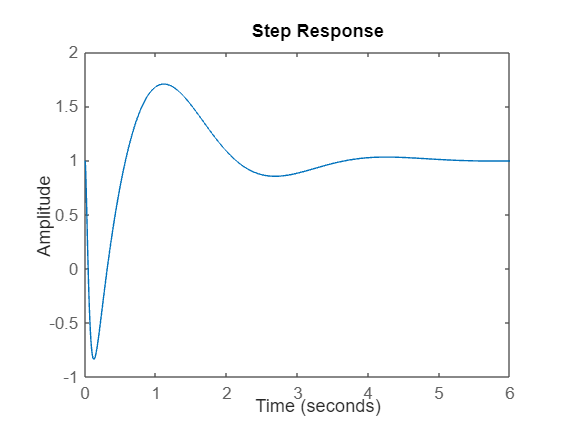

figure(2)
step(TFH)       %plot the step response